
$$\textbf{Q1. Sampling within a Euclidean Plane}$$


(d) (5 points) Implement the algorithm described in the previous sub-question. Use it to sample N = 107 independent points (in 2D) and plot a 2D histogram of the sample. You may use the Matlab function histogram2(), e.g., with ’DisplayStyle’ as ’tile’.


$$\textbf{Algorithm}$$


Here also the idea is same, that is:

Calculate marginal pdf of x (for simplicity marginal pdf is scaled by area, and hence random number generated will

be from 0 to Area instead of 0 to 1)

Find inverse of the CDF of obtained density function.

The obtained inverse is mapping function for x

given x generate random value of y taking a number between 0 andY(x) uniformly

marginal PDF of X = x: (scaled by Area)


$$\[ \begin{cases} 
      \frac{3ex}{\pi} & 0\leq x\leq \pi/3 \\ \\
      \frac{-3e(x - \pi)}{2\pi} &  \pi/3\leq x\leq \pi \\
   \end{cases}
\]$$


marginal CDF of X = x:


$$$a = \frac{-3e}{4\pi}$, 
$b = \frac{3e}{2}$ ,
$c = \frac{-e\pi}{4}$$$



$$\[ \begin{cases} 
      \frac{3ex^{2}}{2\pi} & 0\leq x\leq \pi/3 \\ \\
      ax^{2} + bx + c &  \pi/3\leq x\leq \pi \\
   \end{cases}
\]
$$


inverse = $\textbf{Mapping function of x}$


$$\[ \begin{cases} 
      \sqrt{\frac{2x\pi}{3e}} & 0\leq x\leq \pi e/6 \\ \\
      \frac{-b + \sqrt{b^{2}- 4a(c-x)}}{2a} &  \pi e/6\leq x\leq \pi e/2\\
   \end{cases}
\]$$


So we will take numbers from 0 to πe/2 (area of triangle ) and map it to 0 to π according to above mapping function.

Now given x,y will be choosen uniformly from o to y(x) that is $\textbf{mapping function for y uniform(0,Y(x))}$

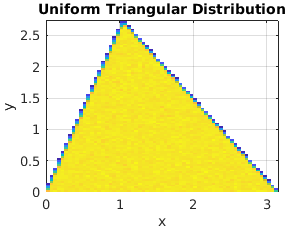

rng(0);
N = 10000000;
z= pi.*exp(1)./6;
a = (-1.*3.*exp(1))./(4.*pi);
b = 3.*exp(1)./2;
c = -1.*pi.*exp(1)./4;
arr = ((pi.*exp(1))./2).*rand(N,1);
x = arrayfun(@(x) (sqrt((2.*pi.*x)./(3.*exp(1)))*(x < z) + ((-b + sqrt(b.*b - 4.*a.*(c -x)))./(2.*a))*(x >= z)), arr);
y = arrayfun(@(x) (((3.*x.*exp(1)./pi).*rand(1,1)).*(x < pi./3) +((2.*a.*(x - pi )).*rand(1,1)).*(x >= pi./3)) , x);
histogram2(x,y,'DisplayStyle','tile');

title("Uniform Triangular Distribution")
xlabel("x")
ylabel("y")